clear; clc; clear path;
addpath ../funcs/.

zeta = 0.1;
omega = 1000;
s = tf([1 0],1);
Ps = (2*zeta*omega*s+omega^2)/(s^2*(s^2+2*zeta*omega+omega^2))

Ps =
 
   200 s + 1e06
  --------------
  s^4 + 1e06 s^2
 
Continuous-time transfer function.
Model Properties


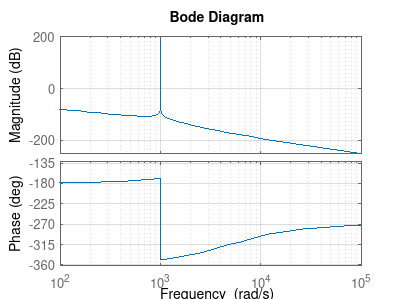

figure(1); clf; hold on;
bode(Ps)
grid on;

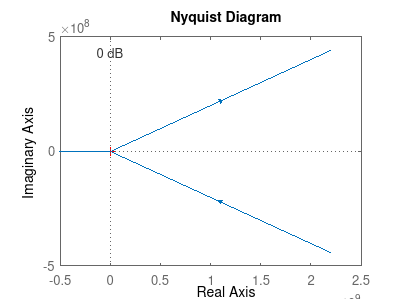

figure(2); clf; hold on;
nyquist(Ps)
grid on;

[z,p,k] = tf2zp([200, 1e6],[1 0 1e6 0 0]);
fprintf("zeros at:\n%d",z);

zeros at:
-5000

fprintf("Poles at:\n")

Poles at:


for i=1:length(p)
    fprintf("%5.0f + %5.0f i\n",real(p(i)),imag(p(i)));
end

    0 +     0 i
    0 +     0 i
   -0 +  1000 i
    0 + -1000 i


fprintf("Gain:\n %d",k);

Gain:
 200

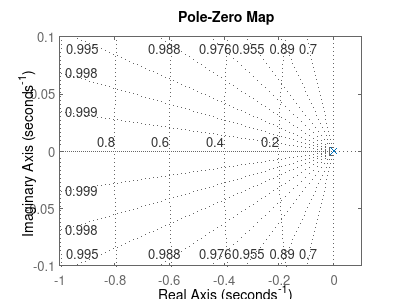

figure(3);clf;
pzplot(Ps)
axis([-1 0.1 -.1 .1])
grid on;

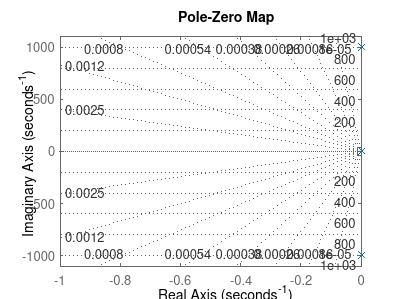


figure(4);clf;
pzplot(Ps)
axis([-1 0 -1100 1100])
grid on;

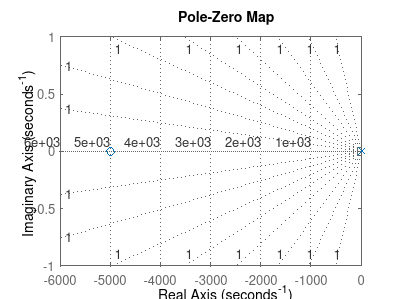

figure(5);clf;
pzplot(Ps)
axis([-6000 0 -1 1])
grid on;

[r,k] = rlocus(Ps)

r = 1.0e+05 *

   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0001i  -0.0000 + 0.0001i  -0.0000 + 0.0001i  -0.0000 + 0.0002i  -0.0000 + 0.0002i  -0.0000 + 0.0003i  -0.0000 + 0.0004i  -0.0000 + 0.0006i  -0.0000 + 0.0008i  -0.0000 + 0.0012i  -0.0000 + 0.0016i  -0.0001 + 0.0023i  -0.0001 + 0.0034i  -0.0004 + 0.0051i  -0.0005 + 0.0053i  -0.0006 + 0.0056i  -0.0007 + 0.0058i  -0.0008 + 0.0060i  -0.0009 + 0.0061i  -0.0010 + 0.0062i  -0.0012 + 0.0063i  -0.0013 + 0.0064i  -0.0015 + 0.0065i  -0.0021 + 0.0068i  -0.0025 + 0.0070i  -0.0036 + 0.0074i  -0.0043 + 0.0077i  -0.0060 + 0.0086i  -0.0077 + 0.0096i  -0.0097 + 0.0107i
   0.0000 + 0.0000i  -0.0000 - 0.0

k = 1.0e+14 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


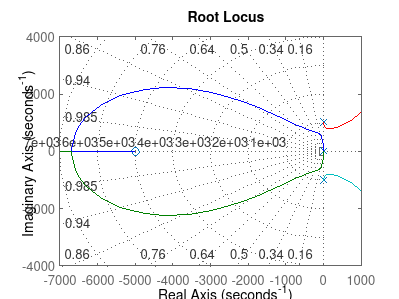

figure(6); clf;
rlocusplot(Ps); grid on;
axis([-7000 1000 -4000 4000])